# EEE3548 Exercise #1

## [2019142047] [전민수(Jeon Minsu)]

#### Q1. Map the real part of $e^{j2\pi(f_xx+f_yy)}$ over the range of -50 to 50 for both x and y. Try using $f_x = f_y = 0.02$.    

Range of -50 to 50

x = -50:50;
y = -50:50;
[X,Y] = meshgrid(x,y);

 
$$f_x = f_y = 0.02$$


f_x = 0.02;
f_y = 0.02;

 
$$e^{j2\pi(f_xx+f_yy)}$$


f = exp(j*2*pi*(f_x*X + f_y*Y));

Real Part of $e^{j2\pi(f_xx+f_yy)}$

Z = real(f);

Result Image

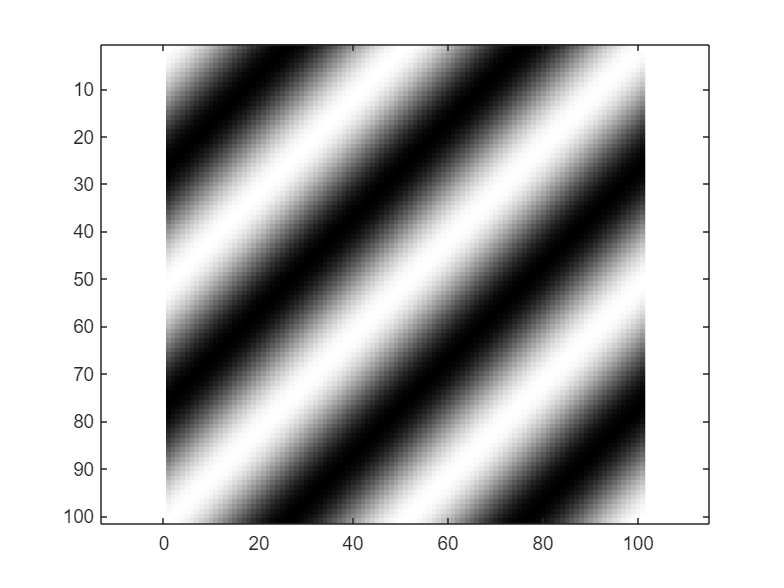

figure;imagesc(Z);colormap gray;axis equal;

#### Q2. Test with different spatial frequency pairs. How would you flip / rotate the direction of the 2D sinusoid?

* To flip -> change plus, minus sign of f_x, f_y

same as Q1

x = -50:50;
y = -50:50;
[X,Y] = meshgrid(x,y); 

change f_x to minus

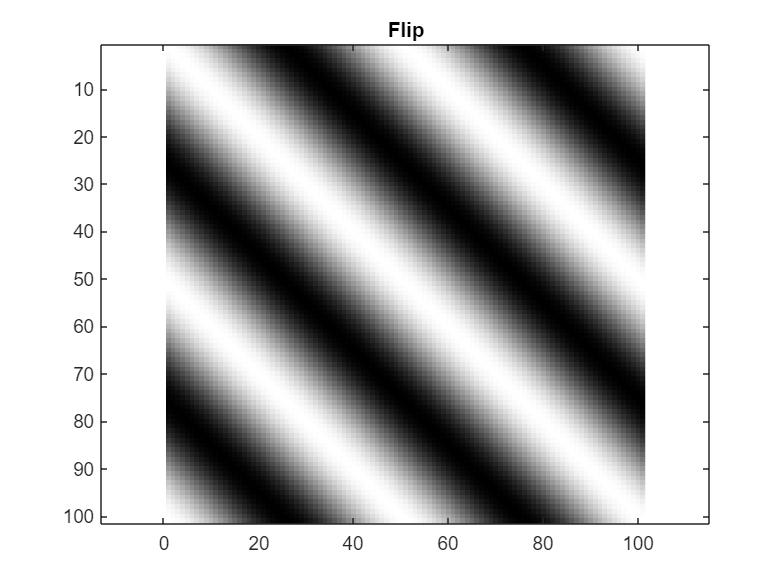

f_x = -0.02;
f_y = 0.02;
f = exp(j*2*pi*(f_x*X + f_y*Y));
Z = real(f);
figure;imagesc(Z);colormap gray;axis equal;title('Flip','fontweight','bold');

To Rotate -> change size of f_x, f_y change size of f_x, f_y

x = -50:50;
y = -50:50;
[X,Y] = meshgrid(x,y);

change f_x, f_y size(to be same as the solution, f_x has to be 0)

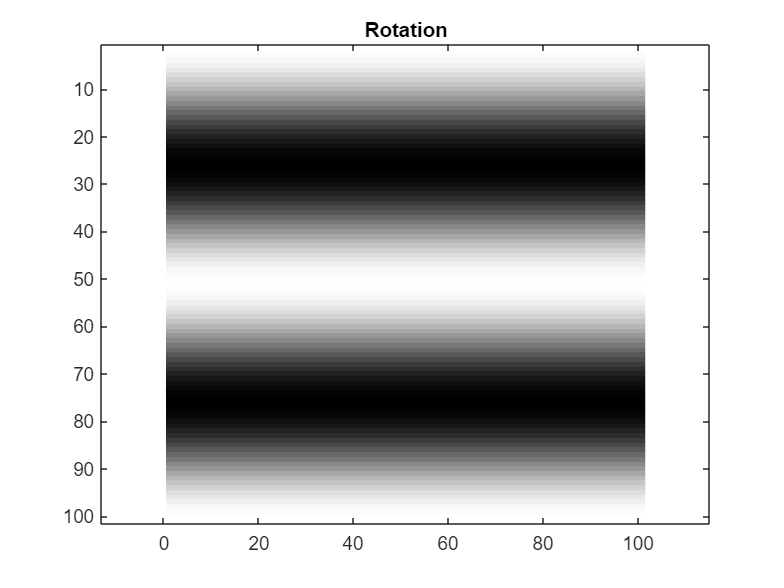

f_x = 0;
f_y = 0.02;
f = exp(j*2*pi*(f_x*X + f_y*Y));
Z = real(f);
figure;imagesc(Z);colormap gray;axis equal;title('Rotation','fontweight','bold');

#### Q3. Defind a function that performs 1D DFT in matrix-vector mutiplication for a given 1D input. (at the end of the file)

Make random array

g = rand(10,1);

Put values in the function(DFT) that we make and print

G = DFT(g)

G =    5.9537 + 0.0000i
  -0.0647 + 0.3066i
   0.2102 - 0.0100i
   0.4322 - 0.8659i
   0.6676 + 0.8000i
   1.2215 - 0.0000i
   0.6676 - 0.8000i
   0.4322 + 0.8659i
   0.2102 + 0.0100i
  -0.0647 - 0.3066i


Compare with fft

G = fft(g)

G =    5.9537 + 0.0000i
  -0.0647 + 0.3066i
   0.2102 - 0.0100i
   0.4322 - 0.8659i
   0.6676 + 0.8000i
   1.2215 + 0.0000i
   0.6676 - 0.8000i
   0.4322 + 0.8659i
   0.2102 + 0.0100i
  -0.0647 - 0.3066i


#### Q4. Compare the speed with the built-in fft function. Try different input sizes.

* Small input sizes

g = rand(3,1);
tic
G = DFT(g);
toc

경과 시간은 0.001839초입니다.


tic
G = fft(g);
toc

경과 시간은 0.001216초입니다.


* large input sizes

g = rand(100,100);
tic
G = DFT(g);
toc

경과 시간은 0.002932초입니다.



tic
G = fft(g);
toc

경과 시간은 0.001946초입니다.


-> fft is faster than DFT function

#### Q5. 2D FFT

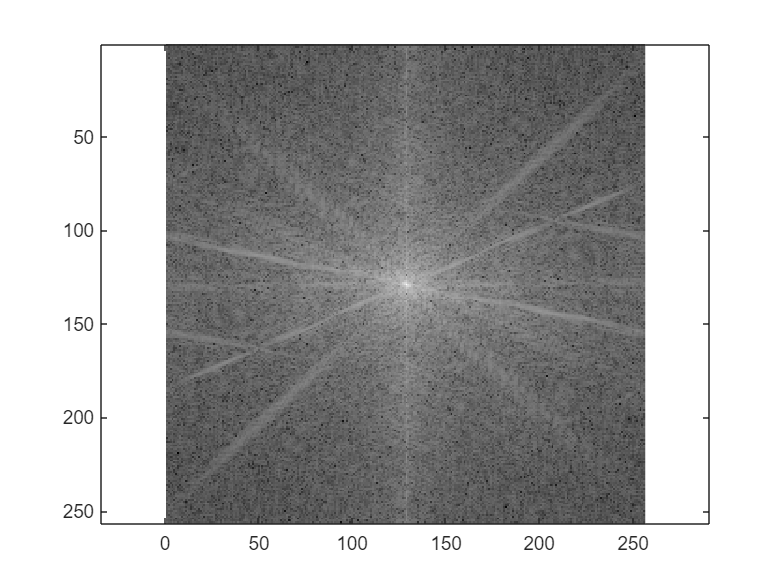

img = imread('cameraman.tif');  % Read Cameramen
fimg = fftshift(fft2(img));     % Do Fourier Transform
figure;imagesc(log(abs(fimg)));colormap gray;axis equal;

#### Q6. Define 2D sinusoidal images as in Q1 in the spatial frequency domain. Take IFT and take abs to visualize it. How can you define the spatial frequencies/directions of the sinusoidal pattern? How would you shift the phase of the sinusoid?�

Real part of $e^{j2\pi(f_xx+f_yy)}$ is $cos(2\pi(f_xx+f_yy))$ and $F[cos{2\pi(f_xx+f_yy)}] = {1 \over 2} ( \delta  (F _{x} -f _{x}, F _{y} -f _{y}) + \delta  (F _{x} +f _{x}, F _{y} +f _{y})) $

So, I will add two delta function $ {1 \over 2} ( \delta  (F _{x} -f _{x}, F _{y} -f _{y}))$ - (delta 1), ${1\over2}\delta  (F _{x} +f _{x}, F _{y} +f _{y})) $ - (delta 2)

And then, do the 2 dimensional Inverse Fourier Transform.

x = -50:50;
y = -50:50;
[F_x,F_y] = meshgrid(x,y);
f_x1 = 5;
f_y1 = 5;
F1 = zeros(size(F_x));                           % 전부 0인 array 생성 
F1(F_x - f_x1 == 0 & F_y - f_y1 == 0) = 1/2;     % Delta 1 추가
F1(F_x + f_x1 == 0 & F_y + f_y1 == 0) = 1/2;     % Delta 2 추가
Sinu =ifft2(ifftshift(F1));                      % 다시 time-domain으로 inverse transform 

Change Frequency -> Change size of f_x, f_y

f_x2 = 3;
f_y2 = 3;
F2 = zeros(size(F_x));                           %전부 0인 array 생성 
F2(F_x - f_x2 == 0 & F_y - f_y2 == 0) = 1/2;     % Delta 1 추가
F2(F_x + f_x2 == 0 & F_y + f_y2 == 0) = 1/2;     % Delta 2 추가
chan_freq =ifft2(ifftshift(F2));                 %다시 time-domain으로 inverse transform 

Change Direction -> Change f_x to minus

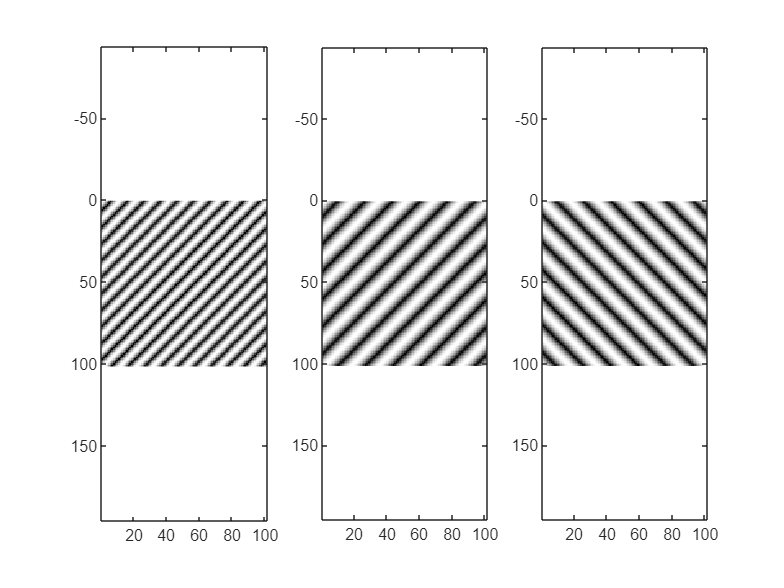

f_x3 = 3;
f_y3 = -3;
F3 = zeros(size(F_x));                           %전부 0인 array 생성 
F3(F_x - f_x3 == 0 & F_y - f_y3 == 0) = 1/2;     % Delta 1 추가
F3(F_x + f_x3 == 0 & F_y + f_y3 == 0) = 1/2;     % Delta 2 추가
chan_dire =ifft2(ifftshift(F3));                 %다시 time-domain으로 inverse transform 

figure();
subplot(1,3,1);imagesc(abs(Sinu));colormap gray;axis equal; %결과출력
subplot(1,3,2);imagesc(abs(chan_freq));colormap gray;axis equal; %결과출력
subplot(1,3,3);imagesc(abs(chan_dire));colormap gray;axis equal; %결과출력

How can you define the spatial frequencies/directions of the sinusoidal pattern? 

-> Change Frequency -> Change size of f_x, f_y / Change Direction -> Change ratio of f_x : f_y

How would you shift the phase of the sinusoid?

-> change the delta1,2 Amplitude

ex. $F[sin{2\pi(f_xx+f_yy)}] = {1 \over 2j} ( \delta  (F _{x} -f _{x}, F _{y} -f _{y}) - \delta  (F _{x} +f _{x}, F _{y} +f _{y})) $

Because when phase of the sinusoid changes, only the Amplitude of each frequency changes.(not the which frequency domain exist.)

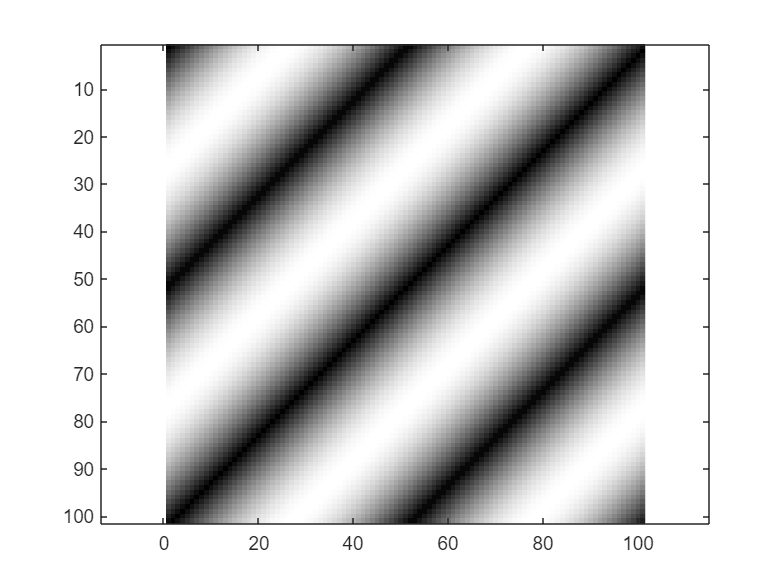

f_x4 = 1;
f_y4 = 1;
F3 = zeros(size(F_x));                           %전부 0인 array 생성 
F3(F_x - f_x4 == 0 & F_y - f_y4 == 0) = j/2;     % Delta 1 추가
F3(F_x + f_x4 == 0 & F_y + f_y4 == 0) = -j/2;    % Delta 2 추가
chan_phas =ifft2(ifftshift(F3));                 % 다시 time-domain으로 inverse transform 

figure;imagesc(abs(chan_phas));colormap gray;axis equal; % 결과출력

#### **Q7. Based on the lecture, perform 2D Linear convolution between the cameraman.tif and 2D gaussian function with **$\sigma$ **= 30. You can use built-in function for 2D gaussian.**

#### **(a) Check the FT of the 2D gaussian function**

#### **(b) Generate 2D Linear convolution using FFT (you may pad zeros to the edge of the images)**

#### **(c) Check the result both the frequency and spatial domain. Discuss the Results**

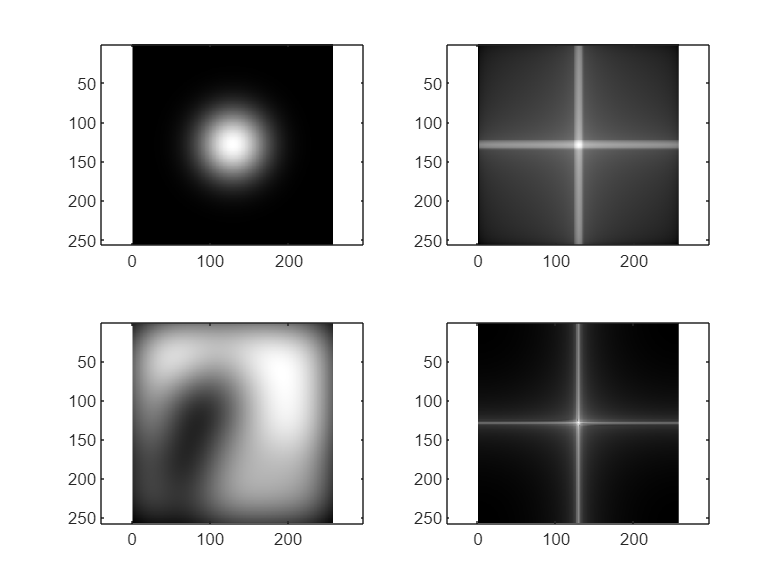

img = imread('cameraman.tif');          % Read Cameramen
gau1 = fspecial('gaussian', 256, 30);   % Make Gaussian for sigma = 30
gau2 = fspecial('gaussian', 256, 3);    % Make Gaussian for sigma = 3
img_new1 = fft_conv(img, gau1);         % Convolution using function

figure();                                                                           % Gaussian Filter for sigma = 30
subplot(2,2,1);imagesc(abs(gau1));colormap gray;axis equal;                         % Check the 2D gaussian function
subplot(2,2,2);imagesc(log(abs(fftshift(fft2(gau1)))));colormap gray;axis equal;    % Check the FT of the 2D gaussian function
subplot(2,2,3);imagesc(real(img_new1));colormap gray;axis equal;
subplot(2,2,4);imagesc(log(abs((fftshift(fft2(img_new1))))));colormap gray;axis equal;

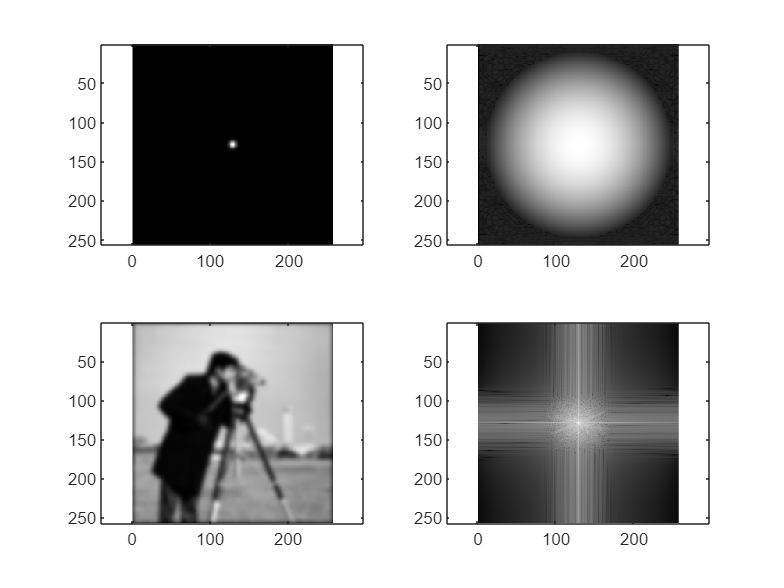

img_new2 = fft_conv(img, gau2);

figure();                                                                           % Gaussian Filter for sigma = 3
subplot(2,2,1);imagesc(abs(gau2));colormap gray;axis equal;                         % Check the 2D gaussian function
subplot(2,2,2);imagesc(log(abs(fftshift(fft2(gau2)))));colormap gray;axis equal;    % Check the FT of the 2D gaussian function
subplot(2,2,3);imagesc(real(img_new2));colormap gray;axis equal;                   
subplot(2,2,4);imagesc(log(abs((fftshift(fft2(img_new2))))));colormap gray;axis equal;

Discuss the Results

The Frequency of Gaussian is clustered in a small frequency region.

So, when we convolution with Gaussian, the amplitude of high frequency of the image decreases and it makes image blurred.

For $\sigma$ = 30, filtered frequency is almost clustered near x axis = 128(F_x = 0), y axis = 128(F_y = 0)

For $\sigma$ = 3, filtered frequency is clustered near x axis = 128(F_x = 0), y axis = 128(F_y = 0), but domain is wider than $\sigma$ = 30.

It means that when sigma is getting bigger, image is getting more blurry.

function G = DFT(g)
    N = length(g);
    m = 0:N-1;
    p = 0:N-1; 
    [M,P] = meshgrid(m,p);
    W = exp(-j*2*pi*(M.*P/N));  % Use the definition for DFT
    G = W*g;
end

function out = fft_conv(img, filter)
    i = length(img);
    f = length(filter);
    img_z = zeros(i+f);                     % Pad Zeros to the edge of the image
    img_z(1:i,1:i) = img; 
    fimg_z = fftshift(fft2(img_z));         % fourier transform for image
    
    filter_z = zeros(i+f);                  % Pad Zeros to the edge of the filter
    filter_z(1:f,1:f) = filter;         
    ffilter_z = fftshift(fft2(filter_z));   % fourier transform for fliter
    
    fimg_new = fimg_z.*ffilter_z;           % Convolution
    img_new = ifft2(ifftshift(fimg_new));   % inverse transform for result 
    out = img_new(i-fix(f/2):i+fix(f/2), i-fix(f/2):i+fix(f/2));    % Select the Range we want
end